# Test the Network

`Copyright (C) 2018 Vitali Rjasanzew-Frey - All Rights Reserved. `

`(`MIT License`)`

THE SOFTWARE IS PROVIDED “AS IS”, WITHOUT WARRANTY OF ANY KIND, EXPRESS OR IMPLIED, INCLUDING BUT NOT LIMITED TO THE WARRANTIES OF MERCHANTABILITY, FITNESS FOR A PARTICULAR PURPOSE AND NONINFRINGEMENT. IN NO EVENT SHALL THE AUTHORS OR COPYRIGHT HOLDERS BE LIABLE FOR ANY CLAIM, DAMAGES OR OTHER LIABILITY, WHETHER IN AN ACTION OF CONTRACT, TORT OR OTHERWISE, ARISING FROM, OUT OF OR IN CONNECTION WITH THE SOFTWARE OR THE USE OR OTHER DEALINGS IN THE SOFTWARE.

## Load the Vineyard_F-RCNN

load('VineyardFastRCNN.mat')

## Show Layers of the Network

frcnn.Network.Layers

ans =   43x1 Layer array with layers:

     1   'imageinput'          Image Input             64x64x3 images with 'zerocenter' normalization
     2   'conv1_1'             Convolution             64 3x3x3 convolutions with stride [1  1] and padding [1  1  1  1]
     3   'relu1_1'             ReLU                    ReLU
     4   'conv1_2'             Convolution             64 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     5   'relu1_2'             ReLU                    ReLU
     6   'pool1'               Max Pooling             2x2 max pooling with stride [2  2] and padding [0  0  0  0]
     7   'conv2_1'             Convolution             128 3x3x64 convolutions with stride [1  1] and padding [1  1  1  1]
     8   'relu2_1'             ReLU                    ReLU
     9   'conv2_2'             Convolution             128 3x3x128 convolutions with stride [1  1] and padding [1  1  1  

## Load your Image

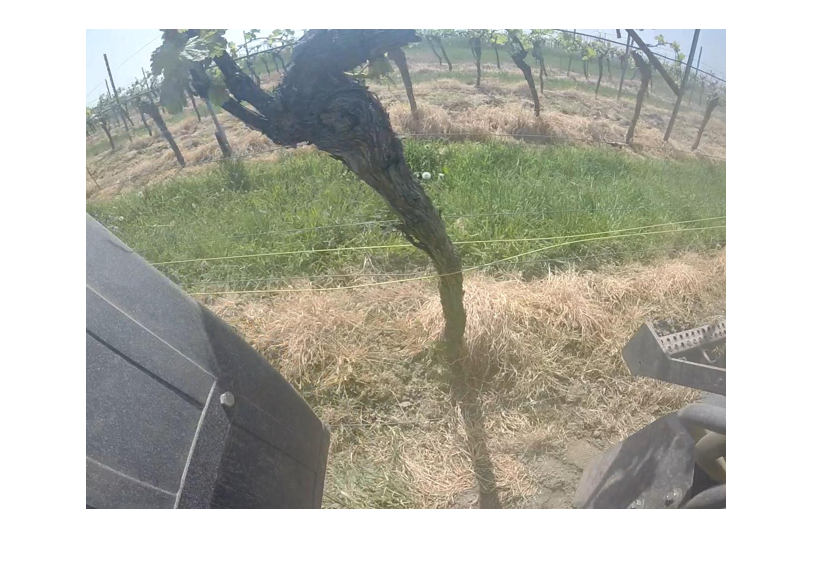

I = imread('yourImage_1.jpg');
imshow(imresize(I, 0.5));

## Detect Obstacle

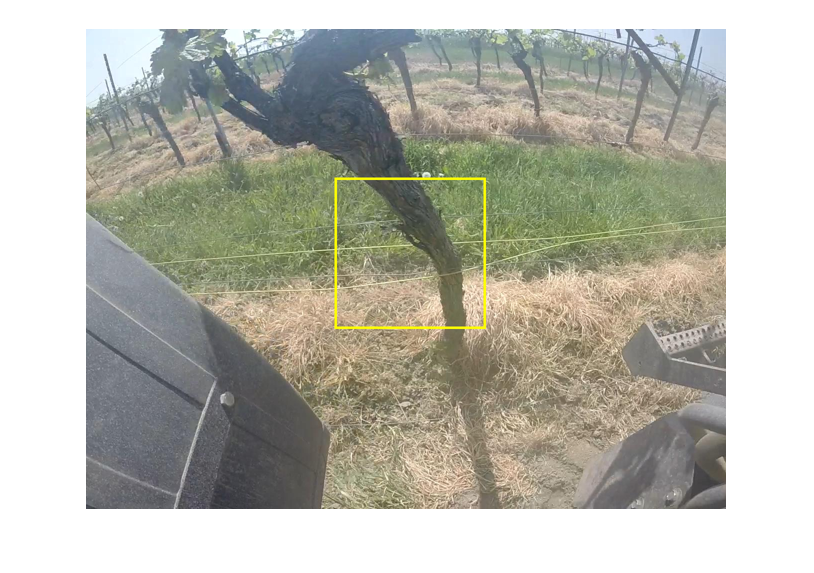

% Detecting Area:
xmin = 500;
ymin = 300;
width = 299;
height = 299;

% Show detection area
detectedImage = insertShape(I,'Rectangle',[xmin ymin width height],'LineWidth',5,'Color','Yellow');
imshow(imresize(detectedImage, 0.5));

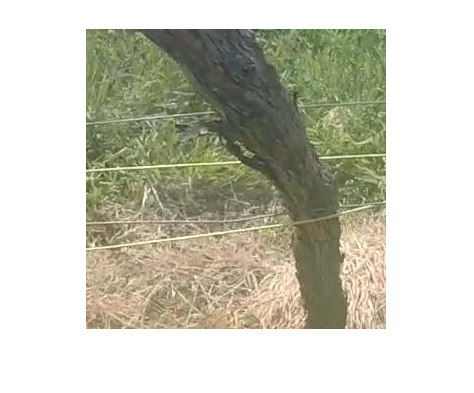


% Crop the Image
imgNew = imcrop(I, [xmin ymin width height]);
imshow(imgNew);

Detected:


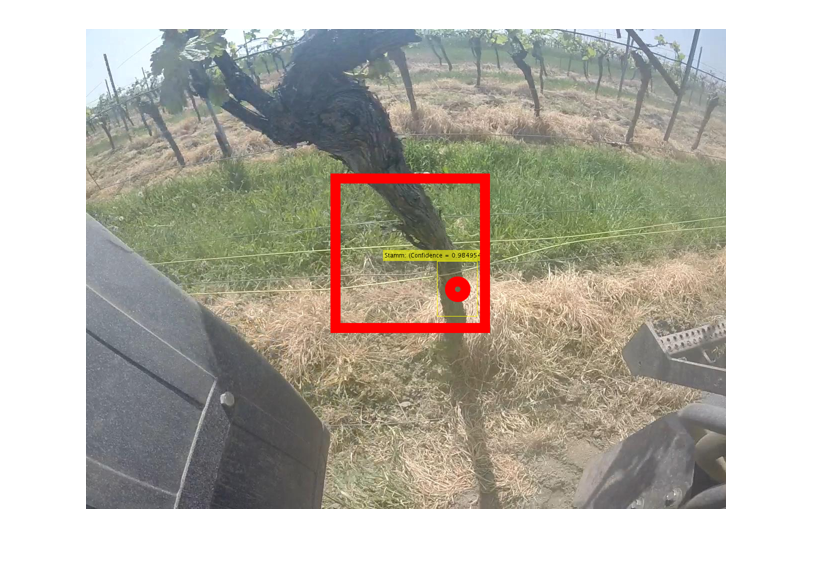


% Use the network to detect obstacles (the first detection can be slow)
[bbox, score, label] = detect(frcnn, imgNew);

% only show the
[score, idx] = max(score);
bbox = bbox(idx, :);

% Check if something has been detected and
% the network is >= 60 % confident

detected = isempty(bbox);
detectionThreshold = 0.6;

if detected == 0 && (score >= 0.6)
    disp('Detected:');
    % draw rectangles and show confidence:
    annotation = sprintf('%s: (Confidence = %f)',label(1), score);
    detectedImg = insertObjectAnnotation(imgNew, 'rectangle', bbox, annotation);
    % calculate circle position
    x_pos = round(bbox(1) + bbox(3)/2);
    y_pos = round(bbox(2) + bbox(4)/2);
    % Insert circle
    detectedImg = insertShape(detectedImg,'circle',[x_pos y_pos 15],'LineWidth',20,'Color','red');
    % insert rectangle
    detectedImage(ymin:(ymin+height),xmin:(xmin+width),:) = detectedImg;
    detectedImage = insertShape(detectedImage,'Rectangle',[xmin ymin width height],'LineWidth',20,'Color','Red');
    imshow(imresize(detectedImage, 0.5));
else
    % Not detected:
    disp('Nothing detected:');
    detectedImage = insertShape(detectedImage,'Rectangle',[xmin ymin width height],'LineWidth',5,'Color','Yellow');
    imshow(imresize(detectedImage, 0.5));
end